**        1.  Energy Conservation**

a) Total energy during one cycle for $\omega_0 =3$, $\theta_0 =0\ldotp 25$, and $\dot\theta_0 = 0$

b) Position and velocity as a function of time

c) Average value of the kinetic and potential energy

d) Phase space, elliptical and clockwise, changes with initial energy, 

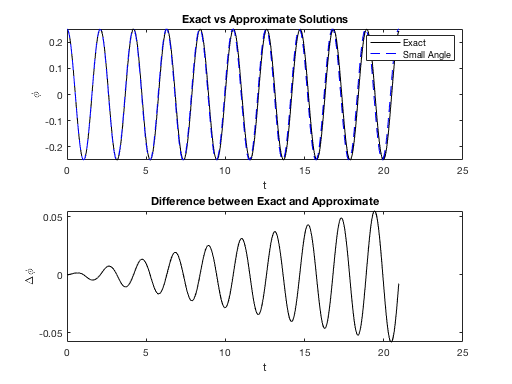

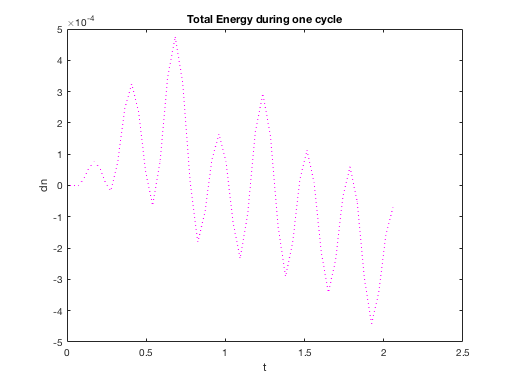

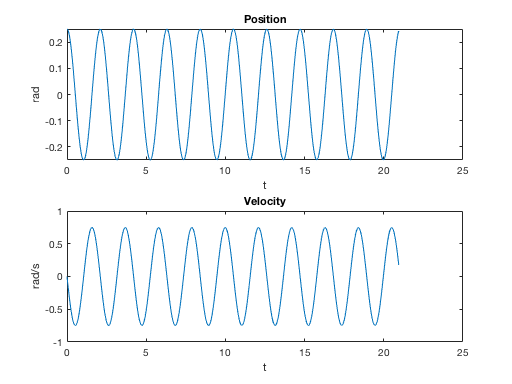

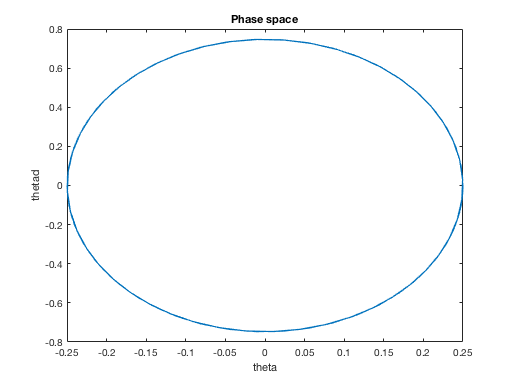

R = 9.81/9;
[period,sol] = pendulum(R,0.25,0);

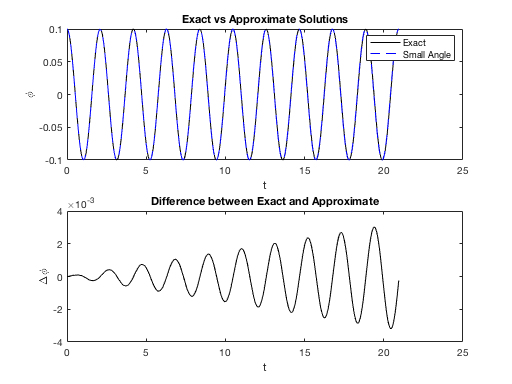

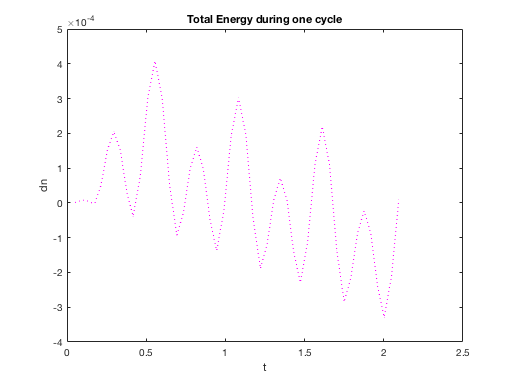

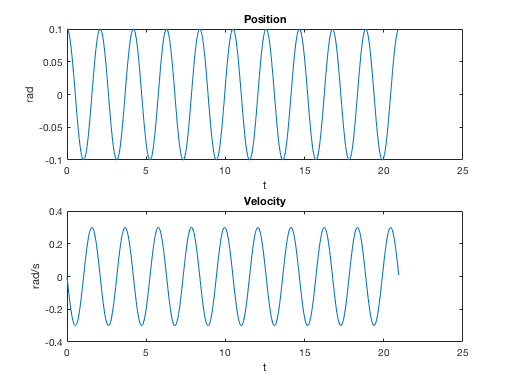

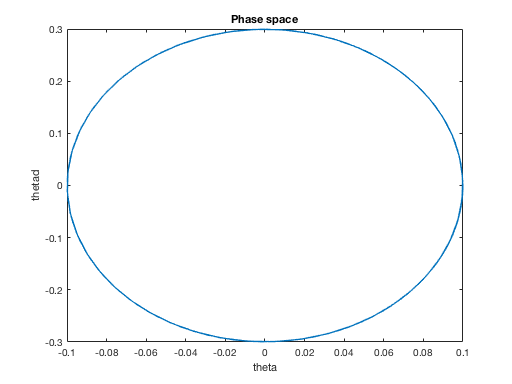

[period,sol] = pendulum(R,0.1,0);

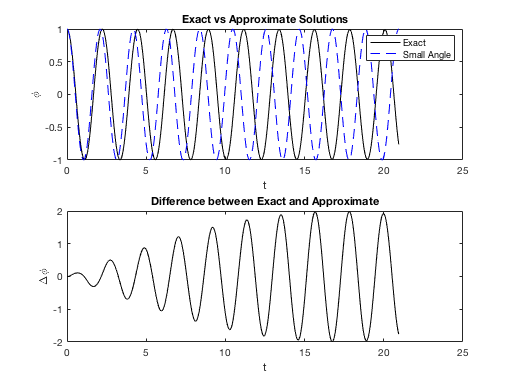

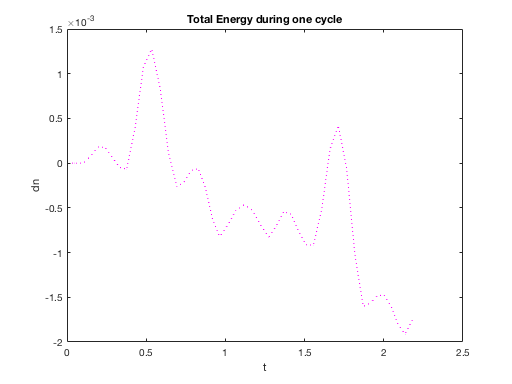

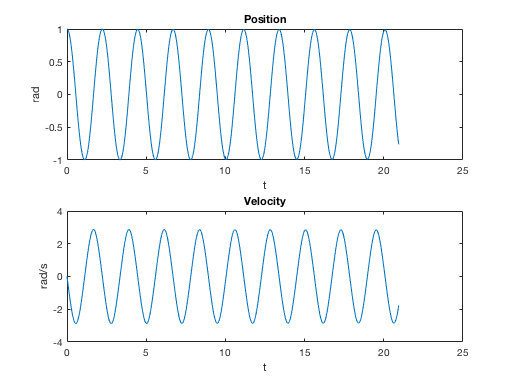

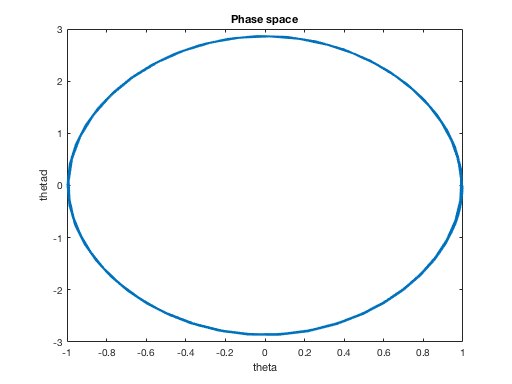

[period,sol] = pendulum(R,1.0,0);

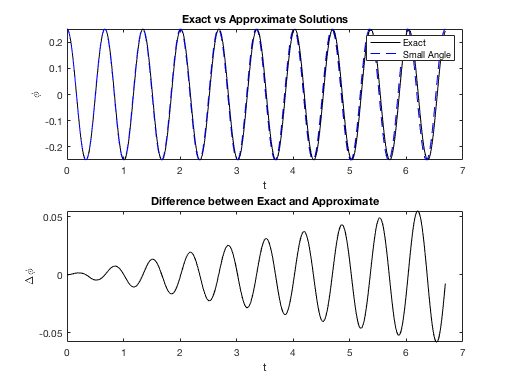

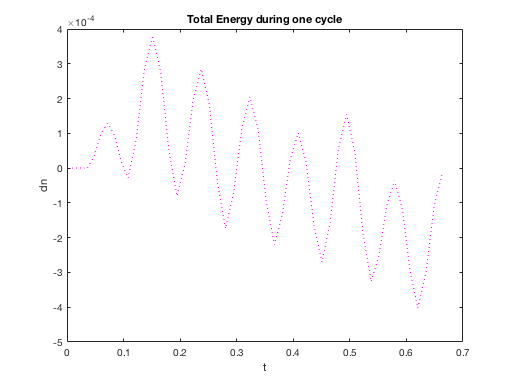

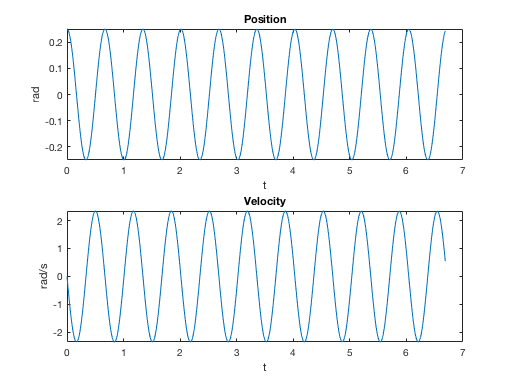

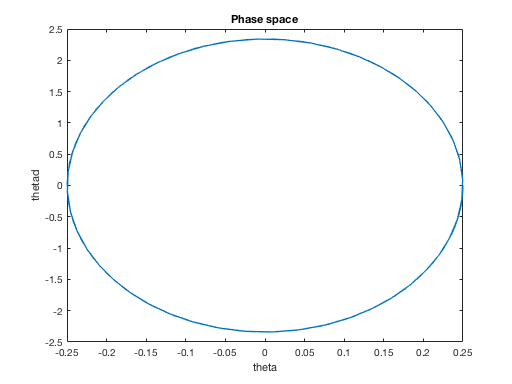

R2 = 1/9;
[period,sol] = pendulum(R2,0.25,0);

**          2.  Large Oscillations**

a) Set g/L = 9

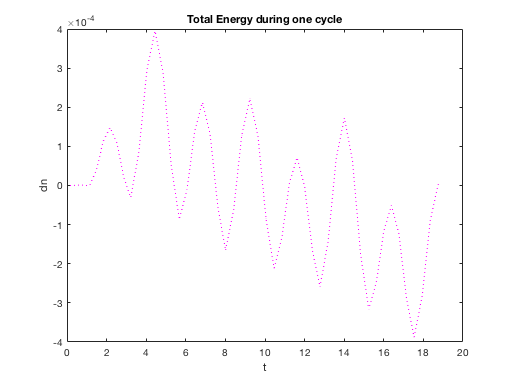

R = 9*9.81;
[period2,sol2] = pendulum2(R,0.25,0,0);

b) Set d theta / dt = 0 at t=0. The period and the maximum amplitude

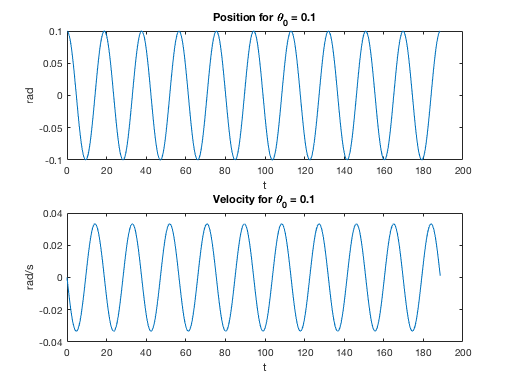

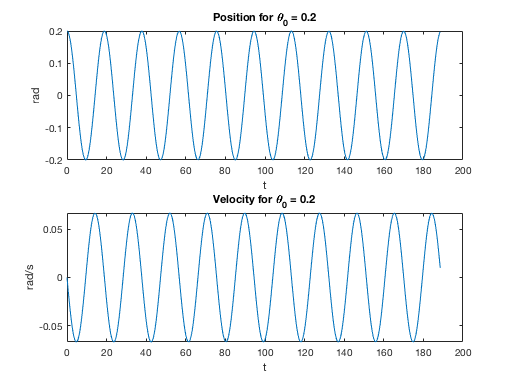

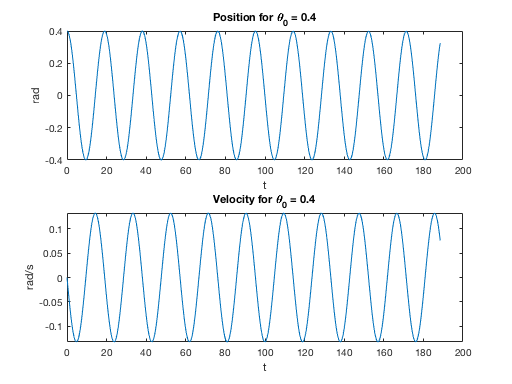

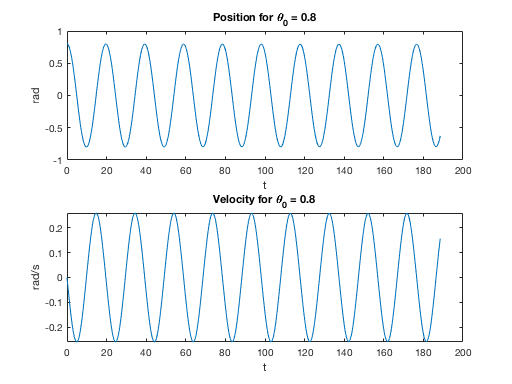

thetaArr= [0.1,0.2,0.4,0.8,1.0];
periodArr = [0,0,0,0,0];
ampArr = [0,0,0,0,0];

for i=1:length(thetaArr)
    theta = thetaArr(i);
    [period2,sol2] = pendulum2(R,theta,0,1);
    w = sol2(:,2);    
    periodArr(i) = period2;
    ampArr(i) = max(w(:,1));
end

Plot T vs max theta:

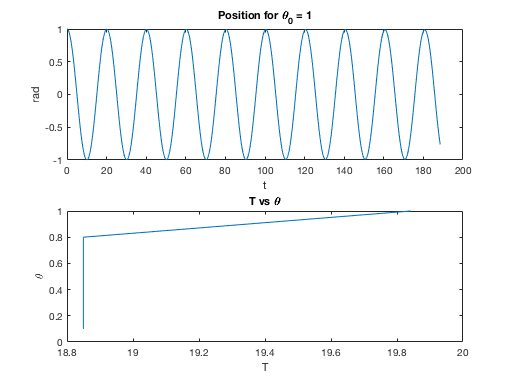

plot(periodArr,ampArr);
title('T vs \theta')
xlabel('T');
ylabel('\theta');

**          3. Damped Oscillations**

a) Add effects of damping for  $\omega_0 =3$, $\theta_0 =0\ldotp 25$, $\dot\theta_0 = 0$ and $\gamma$=0.5

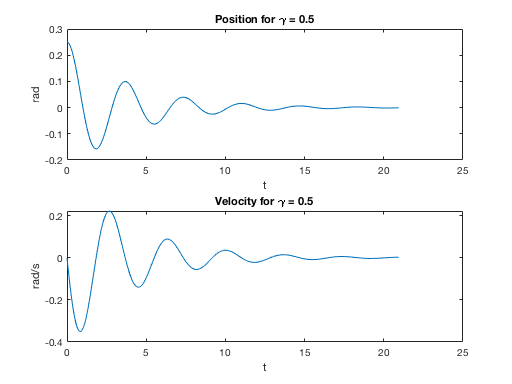

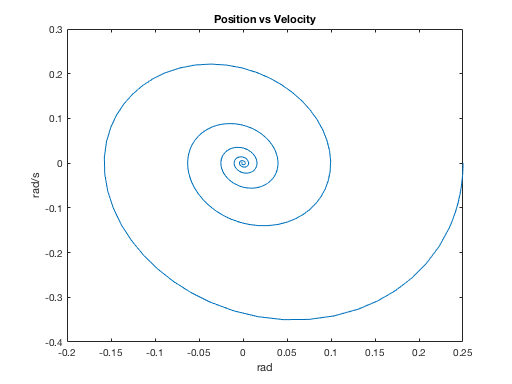

[period3,sol3] = pendulum3(3,3,0.25,0,0.5,1);

    The period is longer compared to the undamped case

b) Additional runs for $\gamma$=1,2,3

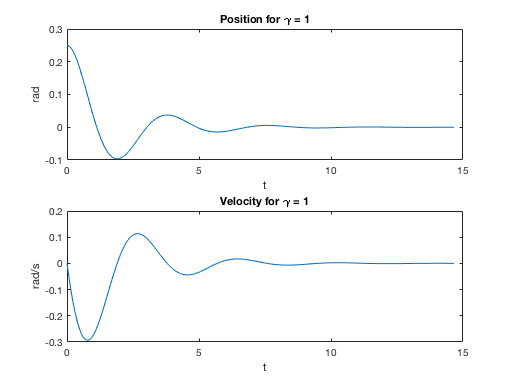

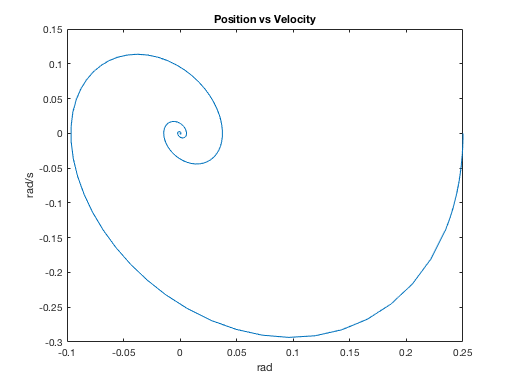

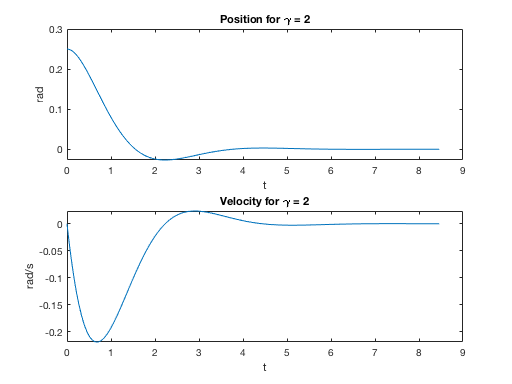

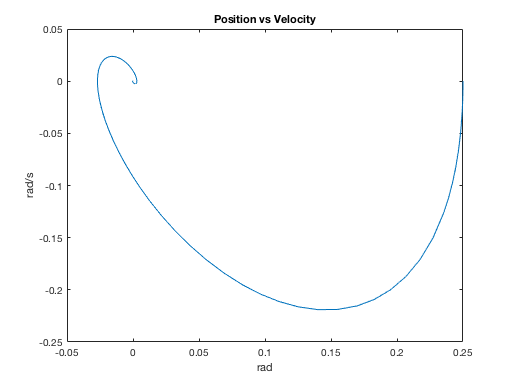

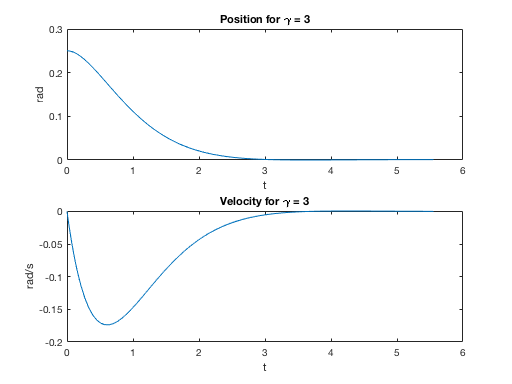

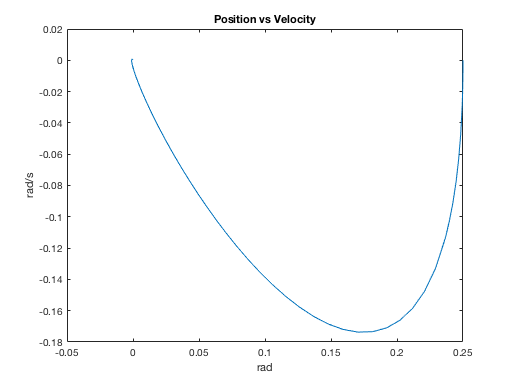

gammaArr = [1,2,3];
freqArr = [0,0,0];

for i=1:length(gammaArr)
    gamma = gammaArr(i);
    [period3,sol3] = pendulum3(3,3,0.25,0,gamma,1);
end

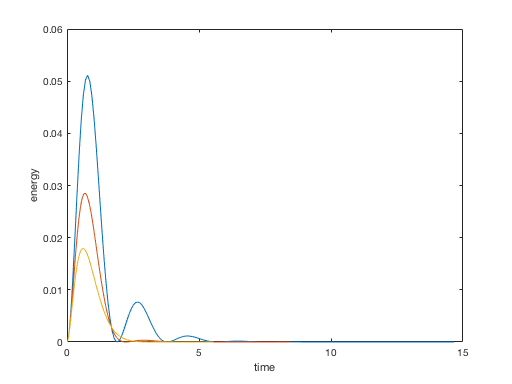

for i=1:length(gammaArr)
    gamma = gammaArr(i);
    [kin,pot,energy,period3,t,w] = pendulum3(3,3,0.25,0,gamma,3);
    plot(t,kin);
    hold on
end
xlabel('time')
ylabel('energy')
hold off

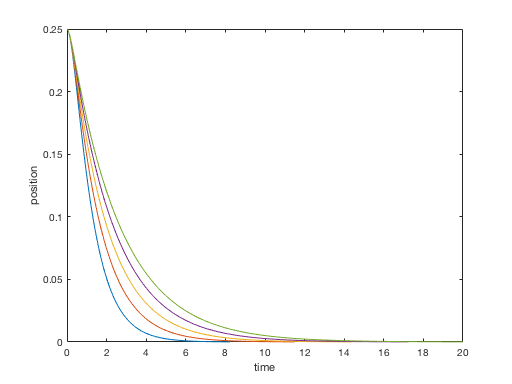

gammaArr2 = [4,5,6,7,8];

for i=1:length(gammaArr2)
    gamma = gammaArr2(i);
    [kin,pot,energy,period3,t,w] = pendulum3(3,3,0.25,0,gamma,3);
    plot(t,w(:,1));
    hold on
end
xlabel('time')
ylabel('position')
hold off

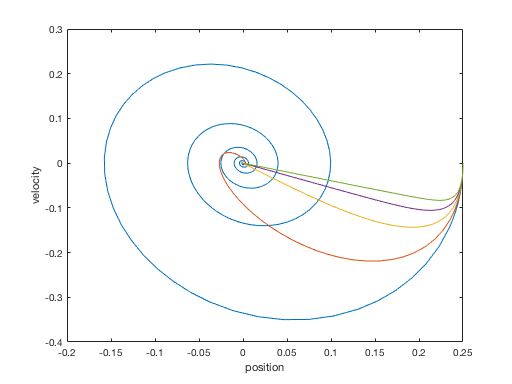

gammaArr3 = [0.5,2,4,6,8];

for i=1:length(gammaArr3)
    gamma = gammaArr3(i);
    [kin,pot,energy,period3,t,w] = pendulum3(3,3,0.25,0,gamma,3);
    plot(w(:,1),w(:,2));
    hold on
end
xlabel('position')
ylabel('velocity')
hold off

**          4. Linear Response to Forced Oscillations**

 a) $\omega_0 =3$, $\omega =2$, $\theta_0 =1$, $\dot\theta_0 = 0$, $\gamma$= 0.5, and $A_0 =1$

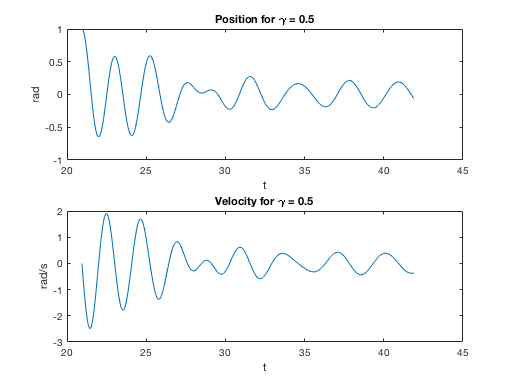

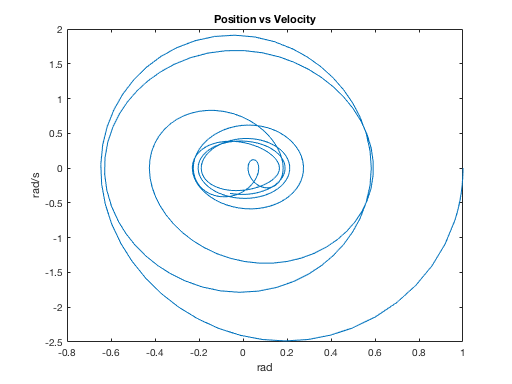

[kin,pot,energy,period4,t,w] = pendulum4(3,2,1,0,0.5,1);

period4

period4 = 2.4640

$\omega_0 =3$, $\omega =2$, $\theta_0 =0$, $\dot\theta_0 = 0$1, $\gamma$= 0.5, and $A_0 =1$

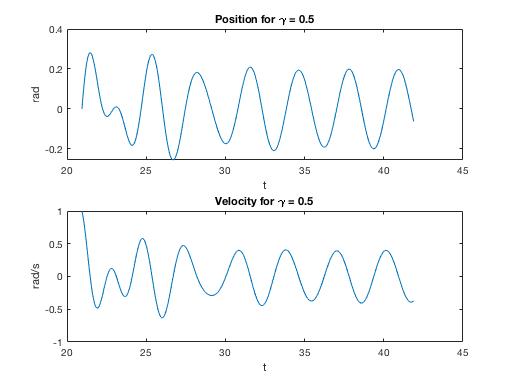

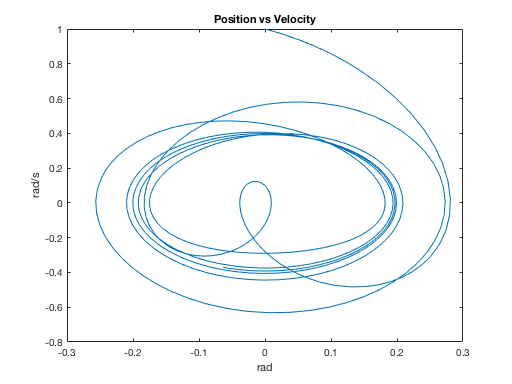

[kin,pot,energy,period4,t,w] = pendulum4(3,2,0,1,0.5,1);

period4

period4 = 2.7250

[kin,pot,energy,period4,t,w] = pendulum4(3,1,0,1,0.5,3);
period4

period4 = 3.5659

[kin,pot,energy,period4,t,w] = pendulum4(3,4,0,1,0.5,3);
period4

period4 = 1.5234


wArray=[0,1.0,2.0,2.2,2.4,2.6,2.8,3.0,3.2,3.4];

for i=1:length(wArray)
    omega=wArray(i);
    g=9.81;
    R = g/3.^2;
    [kin,pot,energy,period4,t,w] = pendulum4(3,omega,0,1,0.5,3);
    [period,sol] = pendulum2(R,0,1,3);
    w2=sol(:,1);
%    phaseArray = w(:,1)-w2(:,1);
    
end

**          5. Resonance**

a) Compute A(ω) for ω=0,1.0,2.0,2.2,2.4,2.6,2.8,3.0,3.2,3.4, $\omega_0 =3$, $\gamma$= 0.5